rng(42);

trainRoot = '/Users/harry/Documents/ELEC5305/FinalProject/S2/TIMIT/TRAIN';
testRoot  = '/Users/harry/Documents/ELEC5305/FinalProject/S2/TIMIT/TEST';

featKind = 'mfcc';     % 'mfcc' or 'logmel'
numMFCC  = 13;
nMels    = 64;

function feat = fe_logmel_stats(y, fs, nMels)
if size(y,2)>1, y = mean(y,2); end
y = y./max(abs(y)+eps);
win = round(0.025*fs); hop = round(0.010*fs);

S = melSpectrogram(y, fs, 'Window',hann(win,'periodic'), ...
                   'OverlapLength',win-hop,'FFTLength',1024, ...
                   'NumBands',nMels,'FrequencyRange',[50 7600]);
logmel = log10(S + 1e-6);

feat = [mean(logmel,2); std(logmel,0,2)]';
end

function feat = fe_mfcc_stats(y, fs, numCoeffs)
if size(y,2)>1, y = mean(y,2); end
y = y./max(abs(y)+eps);
C = mfcc(y,fs,'NumCoeffs',numCoeffs,'LogEnergy','Ignore');
dC = diff(C); ddC = diff(dC);
feat = [mean(C,1), std(C,0,1), mean(dC,1), std(dC,0,1), mean(ddC,1), std(ddC,0,1)];
end

function gender = get_gender(spk)
if startsWith(lower(spk),'f')
    gender = categorical("Female");
else
    gender = categorical("Male");
end
end

%% ===== Dialect: DR1~DR3 =====
Xtr=[];  Ytr=categorical();
Xte=[];  Yte=categorical();

trainDRs = ["DR1","DR2","DR3"];
testDRs  = ["DR1","DR2","DR3"];

% ===== TRAIN =====
for dr = trainDRs
    spkDirs = dir(fullfile(trainRoot, dr, '*'));
    for s = 1:numel(spkDirs)
        if ~spkDirs(s).isdir || startsWith(spkDirs(s).name,'.'), continue; end
        spkPath = fullfile(trainRoot, dr, spkDirs(s).name);

        wavs = dir(fullfile(spkPath,'*.wav'));   % ✅ 必须只读 wav
        if isempty(wavs), continue; end

        for k = 1:numel(wavs)
            fpath = fullfile(spkPath, wavs(k).name);
            [y,fs] = audioread(fpath);

            f = fe_mfcc_stats(y,fs,13);
            if isempty(f), continue; end        % ✅ 防止坏值

            Xtr(end+1,:) = f;
            Ytr(end+1,1) = categorical({char(dr)});
        end
    end
end

% ===== TEST =====
for dr = testDRs
    spkDirs = dir(fullfile(testRoot, dr, '*'));
    for s = 1:numel(spkDirs)
        if ~spkDirs(s).isdir || startsWith(spkDirs(s).name,'.'), continue; end
        spkPath = fullfile(testRoot, dr, spkDirs(s).name);

        wavs = dir(fullfile(spkPath,'*.wav'));
        if isempty(wavs), continue; end

        for k = 1:numel(wavs)
            fpath = fullfile(spkPath, wavs(k).name);
            [y,fs] = audioread(fpath);

            f = fe_mfcc_stats(y,fs,13);
            if isempty(f), continue; end

            Xte(end+1,:) = f;
            Yte(end+1,1) = categorical({char(dr)});
        end
    end
end

% ===== Train SVM =====
Mdl = fitcecoc(Xtr,Ytr,'Learners',templateSVM('KernelFunction','rbf','KernelScale','auto'));

pred = predict(Mdl,Xte);
acc  = mean(pred==Yte)*100;

fprintf("Dialect Accuracy = %.2f%%\n",acc);

Dialect Accuracy = 42.86%


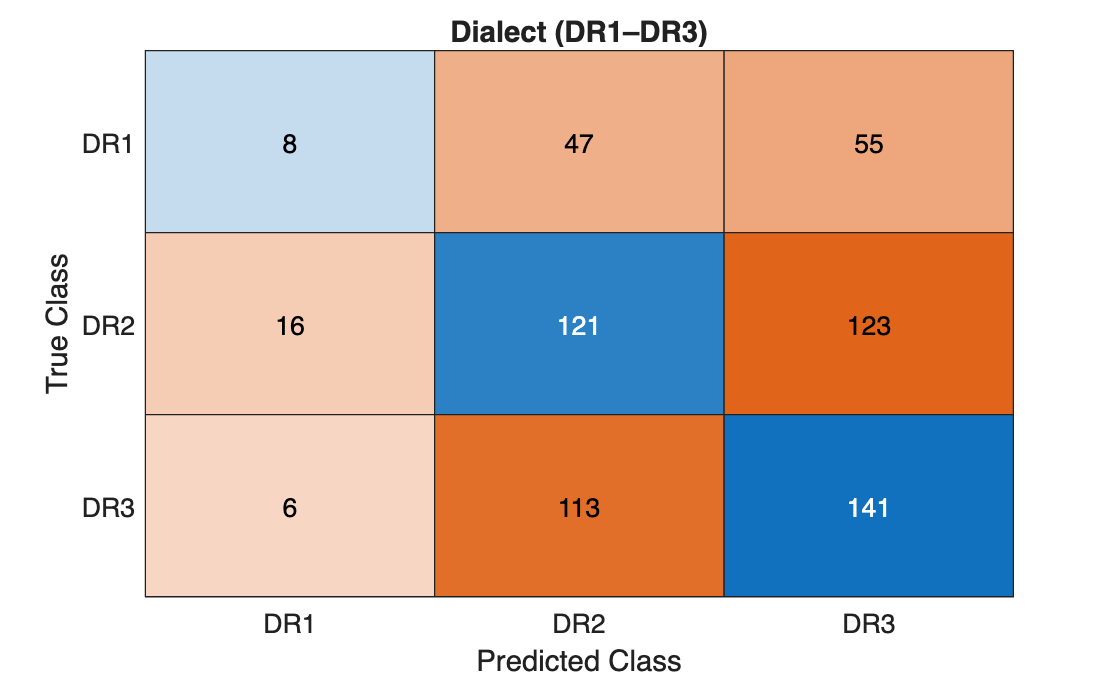

confusionchart(Yte,pred);
title("Dialect (DR1–DR3)");

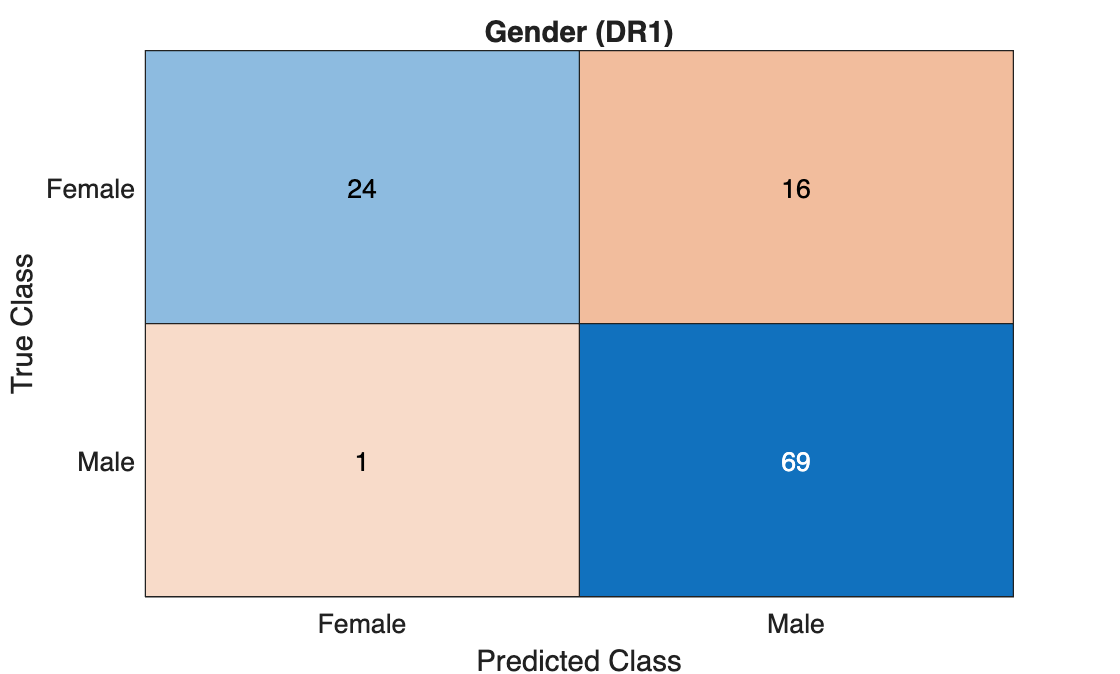

%% ===== Gender: Only DR1 =====
Xtr=[]; Ytr=categorical();
Xte=[]; Yte=categorical();

for root_sel = ["TRAIN","TEST"]
    rootDir = fullfile("/Users/harry/Documents/ELEC5305/FinalProject/S2/TIMIT", root_sel);
    dr = "DR1";

    spkDirs = dir(fullfile(rootDir, dr, '*'));

    for s = 1:numel(spkDirs)
        if ~spkDirs(s).isdir || startsWith(spkDirs(s).name,'.'), continue; end

        spk = spkDirs(s).name;
        if startsWith(lower(spk),'f')
             gender = categorical({'Female'});
        else
              gender = categorical({'Male'});
        end

        wavs = dir(fullfile(spkDirs(s).folder, spk, '*.wav'));

        for k=1:numel(wavs)
            fpath = fullfile(wavs(k).folder,wavs(k).name);
            [y,fs]=audioread(fpath);
            f = fe_mfcc_stats(y,fs,13);

            if strcmp(root_sel,'TRAIN')
                Xtr(end+1,:) = f; Ytr(end+1)=gender;
            else
                Xte(end+1,:) = f; Yte(end+1)=gender;
            end
        end
    end
end

Mdl = fitcsvm(Xtr,Ytr,'KernelFunction','rbf','KernelScale','auto');
pred = predict(Mdl,Xte);

confusionchart(Yte,pred); title("Gender (DR1)");

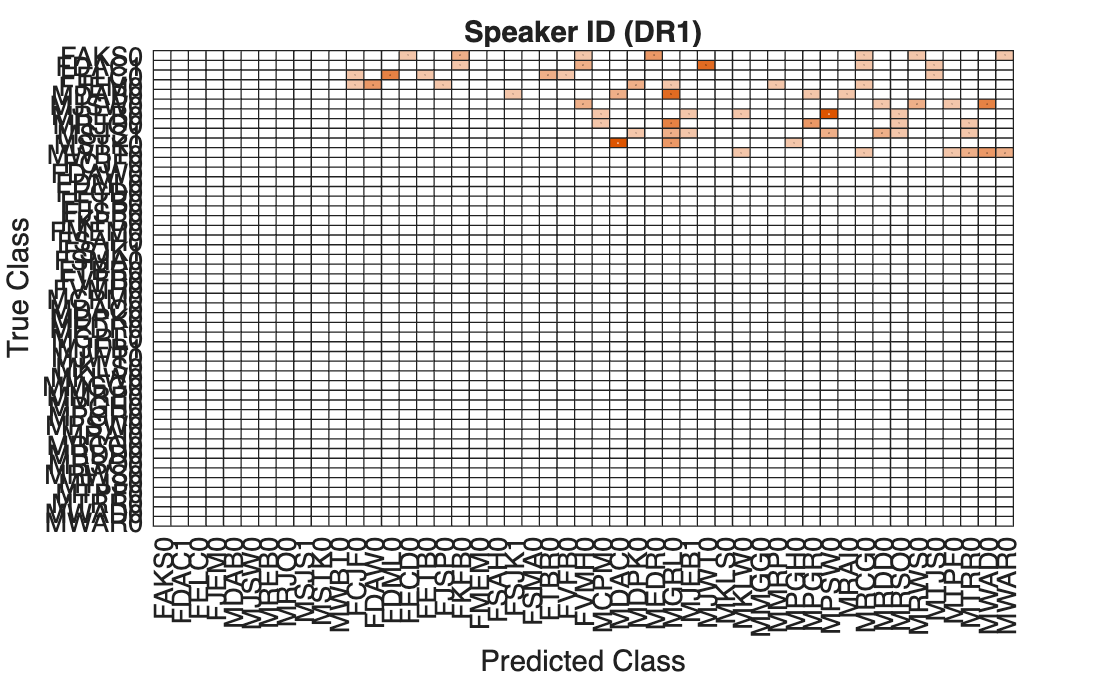

%% ===== Speaker ID: Only DR1 =====
Xtr=[]; Ytr=categorical();
Xte=[]; Yte=categorical();

for root_sel = ["TRAIN","TEST"]
    rootDir = fullfile("/Users/harry/Documents/ELEC5305/FinalProject/S2/TIMIT", root_sel);
    dr = "DR1";

    spkDirs = dir(fullfile(rootDir, dr, '*'));

    for s = 1:numel(spkDirs)
        if ~spkDirs(s).isdir || startsWith(spkDirs(s).name,'.'), continue; end

        spk = spkDirs(s).name;
        wavs = dir(fullfile(spkDirs(s).folder, spk, '*.wav'));

        for k=1:numel(wavs)
            fpath = fullfile(wavs(k).folder,wavs(k).name);
            [y,fs]=audioread(fpath);
            f = fe_mfcc_stats(y,fs,13);

            if strcmp(root_sel,'TRAIN')
                Xtr(end+1,:) = f; Ytr(end+1)= categorical({spk});
            else
                Xte(end+1,:) = f; Yte(end+1)= categorical({spk});
            end
        end
    end
end

Mdl = fitcecoc(Xtr,Ytr,'Learners',templateSVM('KernelFunction','rbf','KernelScale','auto'));
pred = predict(Mdl,Xte);

confusionchart(Yte,pred); title("Speaker ID (DR1)");